# Global Planner Simulation

## Function import

% RUN in file directory
addpath(genpath("../utils/"), genpath("../global_planner/"));

## Initialize

clear all; clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% simulation mode
mode = "static";
% mode = "dynamic";

% start and goal
start = [3, 2];
goal = [18, 29];
% goal = [12, 16];

% planner
% graph search
% planner_name = "a_star";
% planner_name = "dijkstra";
% planner_name = "jps";
% planner_name = "d_star";

% sample search
planner_name = "rrt_star";

## Path planning

% 开始计时
tic;
planner = str2func(planner_name);
[path, flag, cost, expand] = planner(grid_map, start, goal);
% 结束计时并输出经过的时间
elapsedTime = toc;
fprintf('%s执行时间: %.2f 秒\n', planner_name, elapsedTime);

rrt_star执行时间: 14.18 秒


## Visualization

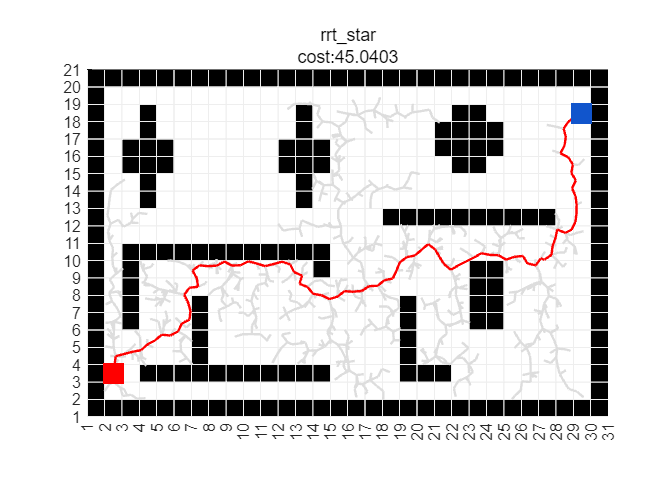

if mode == "static"
    clf; hold on
    
    % plot grid map
    plot_grid(grid_map);
    
    % plot expand zone
    plot_expand(expand, map_size, G, planner_name);
    
    % plot path
    plot_path(path, G);
    
    % plot start and goal
    plot_square(start, map_size, G, "#f00");
    plot_square(goal, map_size, G, "#15c");
    % title
    title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');
    
    hold off
end

## Visualization and modification

Click on the figure to change the state of the grid, the planner will replan.

**Press ENTER in the figure window to exit!**

*Play it!*

if mode == "dynamic"
    while (1)
        clf; hold on
    
        % plot grid map
        plot_grid(grid_map);
    
        % plot expand zone
        plot_expand(expand, map_size, G, planner_name);
    
        % plot path
        plot_path(path, G);
    
        % plot start and goal
        plot_square(start, map_size, G, "#f00");
        plot_square(goal, map_size, G, "#15c");
    
        % title
        title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');
    
        hold off
    
        % get cursor input
        p = ginput(1);
        if size(p, 1) == 0
            % ENTER means nothing
            break;
        else
            c = floor(p);
    
            % change state on the grid map
            grid_map(c(2), c(1)) = 3 - grid_map(c(2), c(1));
    
            % replan
            [path, flag, cost, expand] = planner(grid_map, start, goal);
        end
    end
end